# channel class 설명 및 논문의 데이터 처리 재현과 코멘트

## 0. channel object 생성 및 데이터 처리

**0.2.1 time variable이 없는 retina data 불러와 channel object 만들기**

**parameter 4개**

- `filename`: 같은 디렉토리일 경우 파일이름만, 다른 디렉토리일 경우 전체 경로 포함 입력. MEA data.xlsx 파일의 sheet 1 과 동일한 포맷이어야 함

- `sampleRate` : 데이터 측정 sampling rate(Hz)

- `organoid`**:** organoid 번호 (관리를 위한 번호, 제한 없음) 

- `channel`: channel 번호 (관리를 위한 번호, 제한 없음) 

- `month`: month. 나중에 month별로 종합할 때 사용됨 (관리를 위한 번호, 제한 없음)


%                 
chr = channelReader();
%                                                                        filename,                     organoid, channel, month 
data1 = chr.readRetinaWithoutTime("/Users/mac/Documents/GitHub/neurosignal-matlab/retina/Data 1.csv", 3152, 1,1,1);
%                                                                                                   organoid, channel, month 
data2 = chr.readRetinaWithTime("/Users/mac/Documents/GitHub/neurosignal-matlab/retina/Data 2.csv", 1,1,1);

** bandpass filter preview**

channel object에서 raw 데이터를 불러와서 bandpass filter 적용시 어떤 결과가 나오는지 그래프로 확인

#### data 1.csv

%apply bandpass filter 300-3000hz
bandpass(data1.raw, [300,3000], data1.sf)

#### data 2.csv

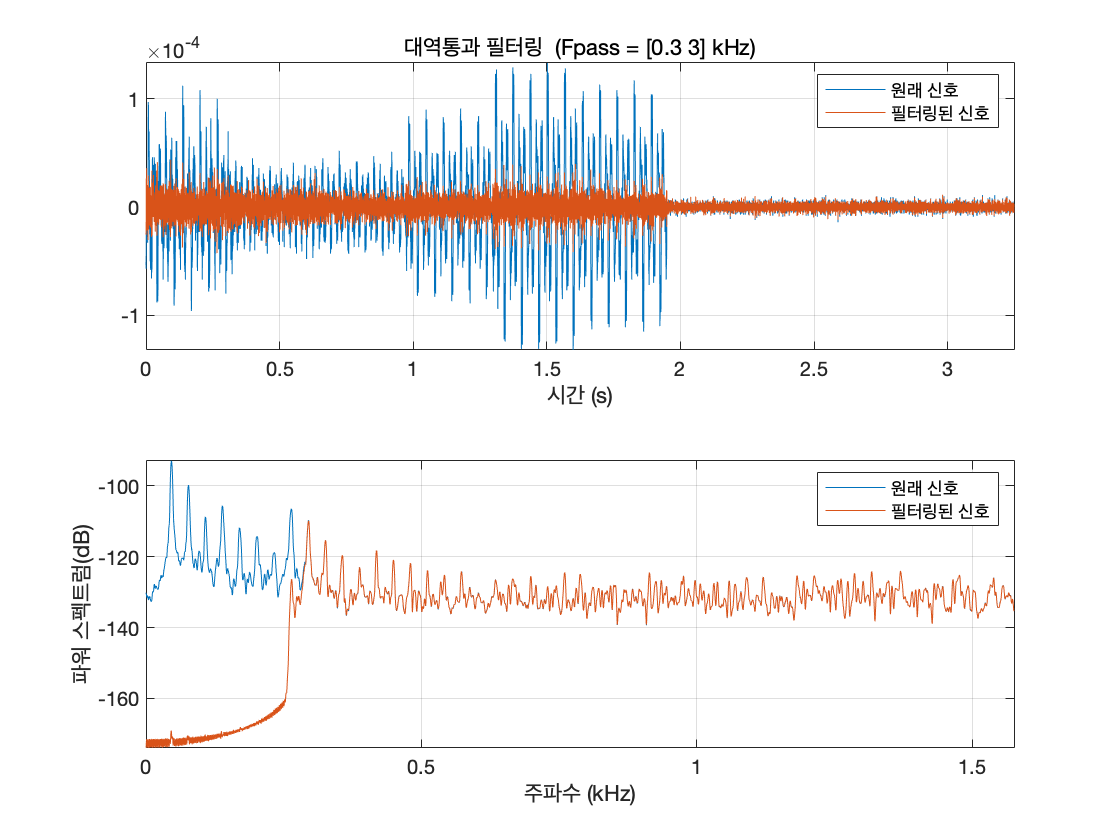

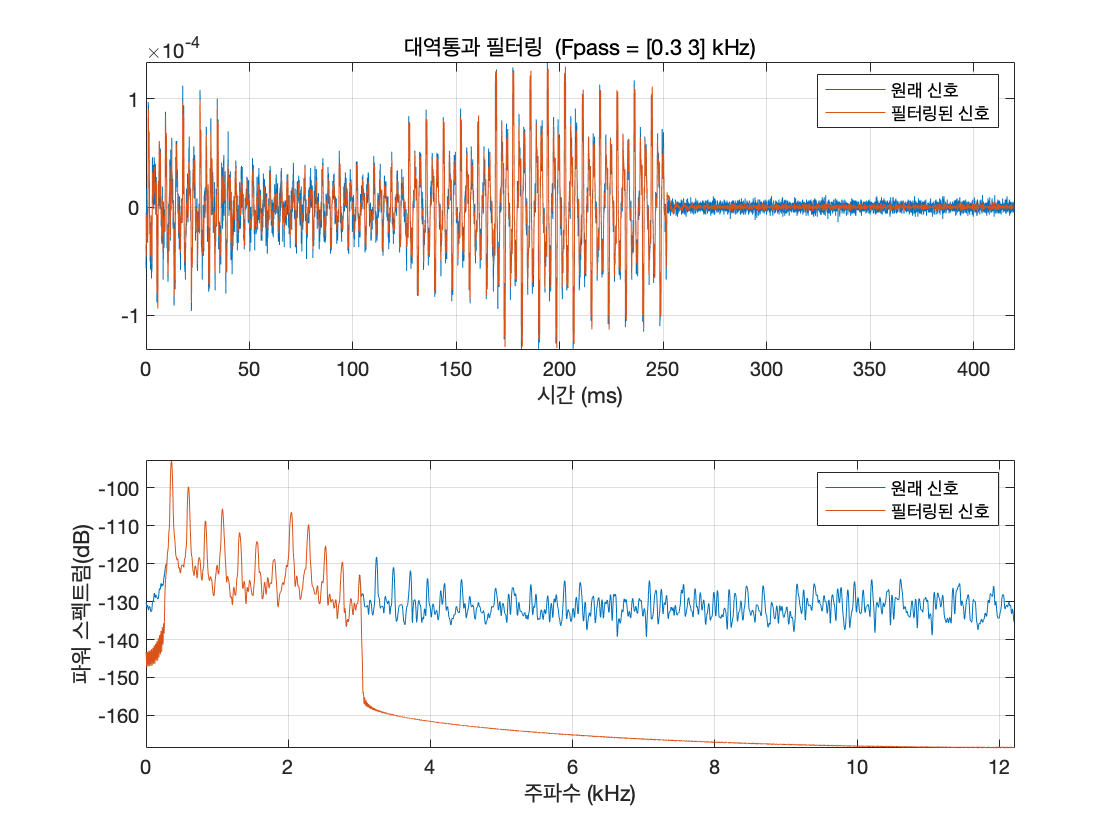

bandpass(data1.raw, [300,3000], data2.sf)

**bandpass filter 적용**

**파라미터 1개 **

- `passBand` : [숫자, 숫자] 포맷으로, hz 단위로 입력

 bandpass filter 실제로 적용하여 channel object 내에 저장

data1.bandPass([300,3000]); %apply bandpass filter 300-3000hz
data2.bandPass([300,3000]); %apply bandpass filter 300-3000hz

**0.4. (method) **`detectSpikes`

**spike detection 수행**

**paramter 3개**

- `thres`: spike 분류 기준. 5를 입력하면 평균+5표준편차 밖의 값을 spike로 분류 ((reference code에서는 5)

- `preTime`: spike waveform의 spike 앞쪽 너비. milisecond 단위 (reference code에서는 2)

- `postTime`: spike waveform의 spike 뒷쪽 너비. milisecond 단위 (reference code에서는 2)

주의: 코드 내 threshold에 minus가 붙어 있음, 즉 이 알고리즘은 local minimum을 찾는 알고리즘. 레퍼런스 코드에서 이렇게 구현되어 있었음.

                        %thres, preTime, postTime
data1.detectSpikes(5,2,2);
data2.detectSpikes(5,2,2);

number of spikes found : 34


number of spikes found : 10007


# **Peri-Stimulus Time Hitogram(PSTH)**

## **(1) PSTH 그리는 코드의 기본 구조 이해**

정원기 님이 보내주신 wallisch2009를 참고하였습니다.

Data 1.csv의 경우, 시간 정보가 없어서 0초부터 시작했다고 가정하고 sample rate를 이용해 시간 변수를 계산하였습니다.

Data 2.csv는 시간 정보가 있었기에 그대로 사용했습니다.

### 0. 데이터 준비

#### **0.1. ****특정 ****amplitude( ****예 ****: 60 ㎶) ****이상의 ****spike ****발생 시 ****counting**

channel object에서 spike detection을 한 결과는 두 attribute에 저장됩니다.

- `data1.spikeTimestamps`: 1d array. spike가 발견된 timestamp를 저장. (https://github.com/CyBrainOrg의 spike detection algorithm의 output)

- `data1.spikeWaveforms`: 2d array. nrow = nSpikes, ncol = waveform 길이(timestamp 단위). spike 앞뒤를 정해진 길이로 잘라 얻은 waveform을 각 row에 저장.

 60 ㎶ 이상의 spike만 골라내려면

- 먼저 `data1.spikeWaveforms의` 각 row의 max값을 취한 뒤 60 이상인 row의 index만 고릅니다.

- `data1.spikeTimestamps에서 그 index에 해당하는 원소만 골라서 저장합니다.`

`제가 voltage측정 단위를 잘 모르기 때문에, 임의의 값 2*10^(-5)를 cutoff로 사용하겠습니다.`

data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 2*1e-5; 
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean)

data1SelectedTimestamp =           25          66         203         289         432         762         839         904        3608        4099        4120        4151        4225        4324        4429        4527        4632        4731        4739        4761        4835        4935        5039        5145        5348        5453        5552        5656        5755        5959        6063


data1SelectedMs = 	1.0e+03 *

    0.0079    0.0209    0.0644    0.0917    0.1371    0.2418    0.2662    0.2868    1.1447    1.3004    1.3071    1.3169    1.3404    1.3718    1.4051    1.4362    1.4695    1.5010    1.5035    1.5105    1.5339    1.5657    1.5987    1.6323    1.6967    1.7300    1.7614    1.7944    1.8258    1.8905    1.9235


#### 0.2. (mili)second 단위로 변환

PSTH를 그릴 때 사용하는 데이터는 spike의 발생 timepoint가 second 혹은 milisecond 단위로 표현된 1d array입니다.

저희가 레퍼런스로 삼은 https://github.com/CyBrainOrg의 코드에서는 spike detection의 output을 timestamp로 내므로, 이를 milisecond 단위로 바꿔 줍니다.

- **data1.startTime** : 데이터의 측정 시작점

- **data1.sf** : sample rate(Hz). timestamp를 이 값으로 나눠주면 second 단위의 표현이 되고, 여기에 1000을 곱하면 milisecond 단위의 표현이 됨.

data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000 %milisecond 단위

data1msPS =  -992.0685 -979.0609 -935.5964 -908.3122 -862.9442 -758.2487 -733.8198 -713.1980  144.6701  300.4442  307.1066  316.9416  340.4188  371.8274  405.1396  436.2310  469.5431  500.9518  503.4898  510.4695  533.9467  565.6726  598.6675  632.2970  696.7005  730.0127  761.4213  794.4162  825.8249  890.5457  923.5406


#### 0.3. Peri-Stimulus: centered relative to an event

특정 event의 timepoint(ex. 원숭이가 팔을 움직이기 시작한 시점, 망막에 빛을 쏜 시점 등)을 위 데이터의 모든 값에서 빼 주면 Peri-Stimulus 상태가 됩니다.

Data 1.csv는 총 3.24초 정도의 길이인데, 1초 시점에서 event가 일어났다고 가정해 보겠습니다. 다음과 같이 뺄셈을 해 주면 Peri-Stimulus 상태가 됩니다.

data1msPS = data1SelectedMs - 1*1000

### 1. edges

time을 작은 구간(bin)으로 쪼개는 기준이 되는 값들입니다. 1d array로 표현되는데, histc 함수에서 이 array를 bin으로 바꾸는 방식이 특이합니다.

예를 들어 edges = [1,2,3,4]일 때, histc 함수는 [1,2), [2,3), [3,4), {4}로 변환합니다. 즉, 3개의 right-open interval과 하나의 singleton으로 변환합니다.

실제 bin별 count를 저장할 1d arrary를 만들고 psth라고 이름을 붙였습니다.

구간을 정할 때는 위에서 준비한 데이터의 max, min을 보고 적당히 시작점, 끝점, 구간 길이를 정합니다. 저는 숫자가 깔끔하게 나오도록 약간 넓게 잡겠습니다.

max(data1msPS)

ans = 923.5406

min(data1msPS)

ans = -992.0685

edges = [-1000: 100: 1000] %시작점 : 구간길이 : 끝점

edges =        -1000        -900        -800        -700        -600        -500        -400        -300        -200        -100           0         100         200         300         400         500         600         700         800         900        1000


psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

### 2. histc

이제 histc함수를 이용해서, 0에서 준비한 데이터를 1에서 만든 bin에 차곡차곡 분리해서 넣고 개수를 셉니다.

책의 예제에서는 여러  trial이 있는 경우를 가정해서  for loop를 썼지만, 여기서는 일단 단 하나의 trial이 있는 상황으로 생각하여 for loop를 빼겠습니다.

또한 책에서는 y축이 # of spikes이지만, 저희는 firing rate를 plot하는 것이 목적이므로, psth를 bin size(100ms)로 나누겠습니다.

psth = psth + histc(data1msPS,edges)

psth =      8     2     6     0     0     0     0     0     0     0     0     2     0    10     6    12     4     6     4     2     0


psth = psth / 100

psth =     0.0800    0.0200    0.0600         0         0         0         0         0         0         0         0    0.0200         0    0.1000    0.0600    0.1200    0.0400    0.0600    0.0400    0.0200         0


### 3. bar

막대그래프를 그려주는 bar 함수를 이용해 히스토그램을 그립니다.

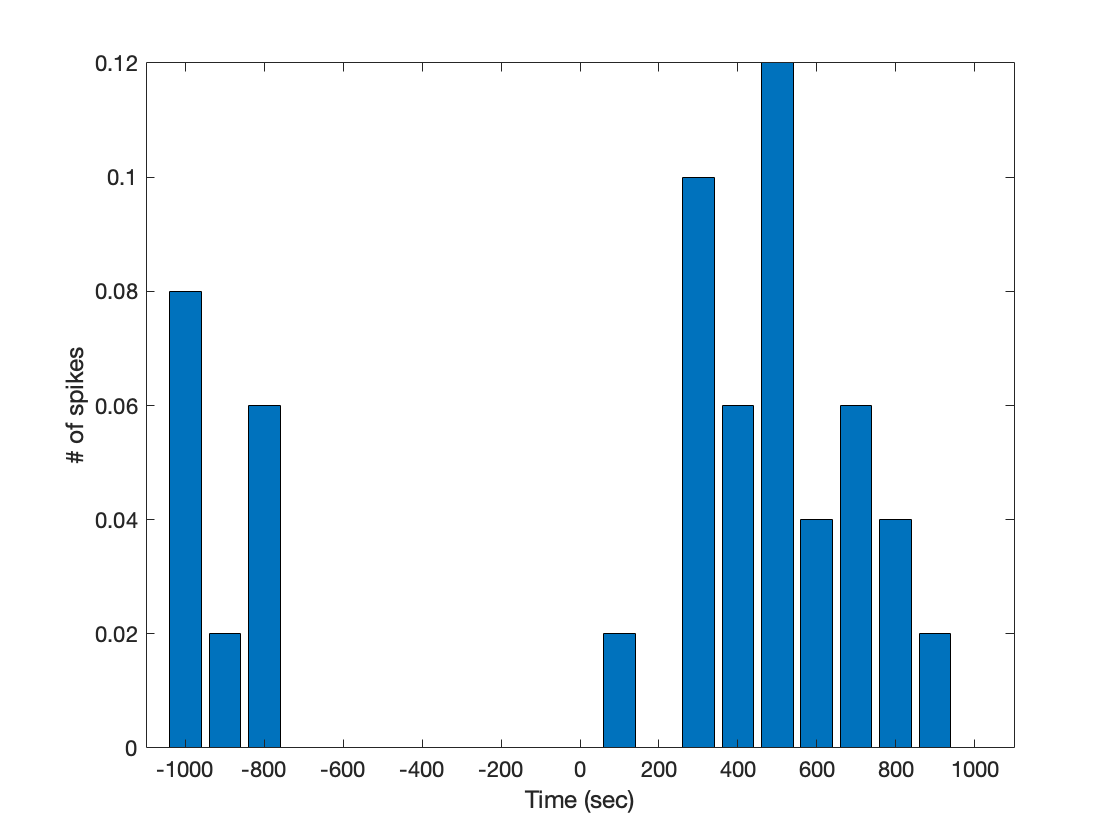

figure
bar(edges,psth); %Plot PSTH as a bar graph 
xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (sec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

지금까지의 코드를 한 단락으로 정리하면 다음과 같습니다.

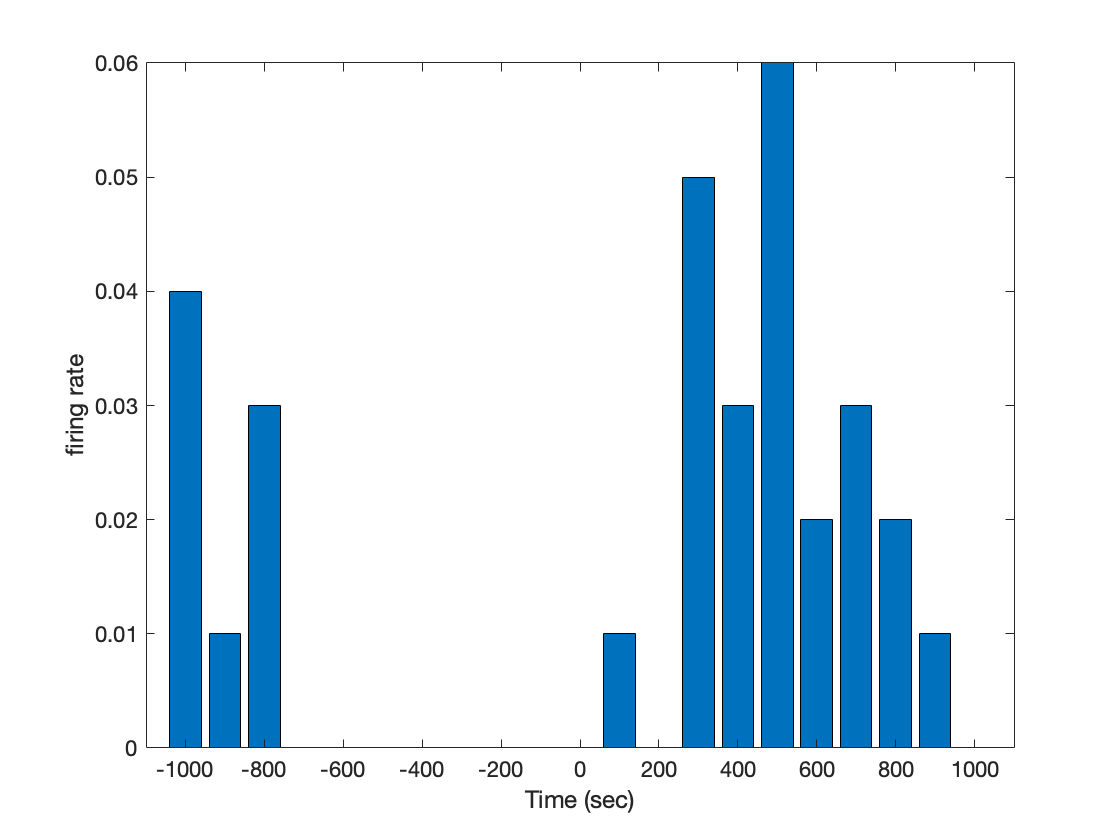

% 0.1. cutoff spikes
data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 2*1e-5; 
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean);

% 0.2. into miliseconds
data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000; %milisecond 단위

% 0.3. Peri-Stiumulus
data1msPS = data1SelectedMs - 1*1000;

% 1. edges
max(data1msPS);
min(data1msPS);
edges = [-1000: 100: 1000]; %시작점 : 구간길이 : 끝점
psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

%2. histc
psth = psth + histc(data1msPS,edges);
psth = psth / 100;

%3. bar
figure
bar(edges,psth); %Plot PSTH as a bar graph 
xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (milisec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

## (2) 여러 trial average하기

Data 1.csv와 Data 2.csv 가 같은 source의 서로 다른 trial이라고 가정하고, for loop를 이용해 averageing해 보겠습니다.

두 데이터의 차이점이 두 개 있어서, 이를 보정해 주어야 합니다.

-  Data 2.csv는 시작점이 1.2초 쯤인 반면 저희가 Data 1.csv는 0초에 시작했다고 가정했다는 점

- 두 번째는 Data2.csv가 훨씬 긴 시간동안 측정되었다는 점.

그런데, 두 번째 차이점은 보정해 줄 필요가 없습니다. histc함수가 어차피 주어진 bin에 들어가지 않는 범위의 값은 count하지 않기 때문입니다.

이 두 차이점은, 실제로 두 데이터가 같은 source의 서로 다른 trial이었으면 발생하지 않았을 것입니다. 따라서 실제로 averaging을 할 때는 위 문제를 신경쓰지 않아도 됩니다.

먼저  data1.csv를 위에서 했던 것과 똑같이 전처리합니다.

%%Data 1.csv

% 0.1. cutoff spikes
data1SpikesMax = max(data1.spikeWaveforms, [], 2); %max for each row
data1SelectedIdxBoolean = data1SpikesMax > 2*1e-5; 
data1SelectedTimestamp = data1.spikeTimestamps(data1SelectedIdxBoolean);

% 0.2. into miliseconds
data1SelectedMs = (data1.startTime + data1SelectedTimestamp / data1.sf) * 1000; %milisecond 단위

% 0.3. Peri-Stiumulus
data1msPS = data1SelectedMs - 1*1000

data1msPS =  -992.0685 -979.0609 -935.5964 -908.3122 -862.9442 -758.2487 -733.8198 -713.1980  144.6701  300.4442  307.1066  316.9416  340.4188  371.8274  405.1396  436.2310  469.5431  500.9518  503.4898  510.4695  533.9467  565.6726  598.6675  632.2970  696.7005  730.0127  761.4213  794.4162  825.8249  890.5457  923.5406


이제 Data 2.csv 를 처리합니다.  spike가 초반에 별로 발생하지 않아서, 1.2초를 0초으로 바꾸는 변환을 해도 Data 1.csv의 spike 분포 시간 구간과 맞지 않습니다. 적당히 30초 정도를 0초로 바꾸겠습니다.

%%Data 2.csv

% 0.1. cutoff spikes
data2SpikesMax = max(data2.spikeWaveforms, [], 2); %max for each row
data2SelectedIdxBoolean = data2SpikesMax > 2*1e-5; 
data2SelectedTimestamp = data2.spikeTimestamps(data2SelectedIdxBoolean);

% 0.2. into miliseconds
data2SelectedMs = (data2.startTime + data2SelectedTimestamp / data2.sf) * 1000; %milisecond 단위

%0.2.1. 시작점 바꾸기
data2SelectedMs = data2SelectedMs - (30 * 1000);


% 0.3. Peri-Stiumulus
data2msPS = data2SelectedMs - 1*1000

data2msPS = 	1.0e+04 *

   -2.6291   -2.6275   -2.6258   -2.6241   -2.6225   -2.6208   -2.6191   -2.6175   -2.6158   -2.6141   -2.6125   -2.6108   -2.6093   -2.6076   -2.6059   -2.6057   -2.6046   -2.6043   -2.6040   -2.6037   -2.6029   -2.6026   -2.6023   -2.6020   -2.6014   -2.6011   -2.6009   -2.6007   -2.6004   -2.6000   -2.5997   -2.5995   -2.5990   -2.5987   -2.5983   -2.5981   -2.5978   -2.5976   -2.5973   -2.5970   -2.5967   -2.5964   -2.5961   -2.5957   -2.5954   -2.5950   -2.5948   -2.5945   -2.5940   -2.5937


이제 PSTH를 그립니다. for loop를 쓰려면 일단 data1msPS와 data2msPS를 묶어야 하는데, 책에 나온 데로 struct를 사용합니다.

dataBundle = struct("times", {data1msPS, data2msPS})

dataBundle = 다음 필드를 포함한 1×2 struct 배열:
    times


dataBundle(1).times % data1msPS

ans =  -992.0685 -979.0609 -935.5964 -908.3122 -862.9442 -758.2487 -733.8198 -713.1980  144.6701  300.4442  307.1066  316.9416  340.4188  371.8274  405.1396  436.2310  469.5431  500.9518  503.4898  510.4695  533.9467  565.6726  598.6675  632.2970  696.7005  730.0127  761.4213  794.4162  825.8249  890.5457  923.5406


dataBundle(2).times % data2msPS

ans = 	1.0e+04 *

   -2.6291   -2.6275   -2.6258   -2.6241   -2.6225   -2.6208   -2.6191   -2.6175   -2.6158   -2.6141   -2.6125   -2.6108   -2.6093   -2.6076   -2.6059   -2.6057   -2.6046   -2.6043   -2.6040   -2.6037   -2.6029   -2.6026   -2.6023   -2.6020   -2.6014   -2.6011   -2.6009   -2.6007   -2.6004   -2.6000   -2.5997   -2.5995   -2.5990   -2.5987   -2.5983   -2.5981   -2.5978   -2.5976   -2.5973   -2.5970   -2.5967   -2.5964   -2.5961   -2.5957   -2.5954   -2.5950   -2.5948   -2.5945   -2.5940   -2.5937


averaging을 하므로, firing rate를 추가로 trial 개수로 나눠 주어야 합니다.

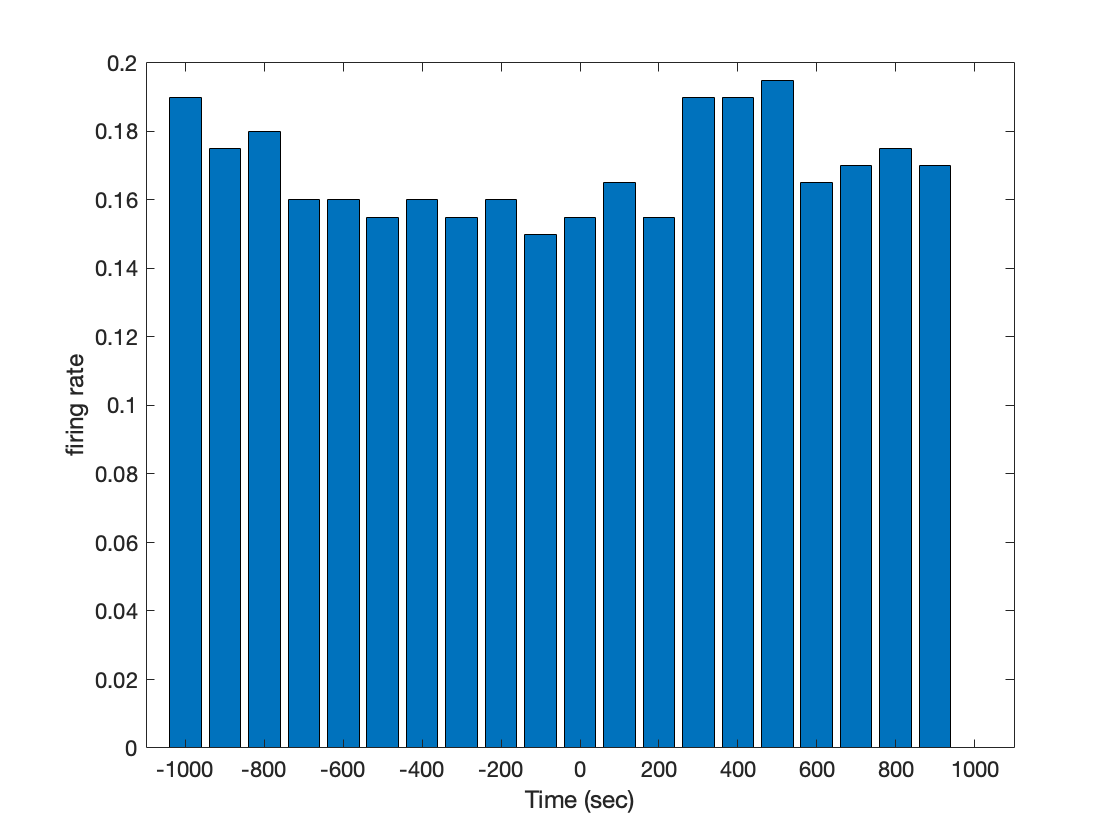

% 1. edges

edges = [-1000: 100: 1000]; %시작점 : 구간길이 : 끝점
psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

%2. histc with for loop
for j  = 1:2
    psth = psth + histc(dataBundle(j).times,edges);
end
psth = (psth / 100) / 2; %averaging

%3. bar
figure
bar(edges,psth); %Plot PSTH as a bar graph 
xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (milisec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 

# Raster plot

raster plot은  https://github.com/CyBrainOrg의 코드에도 그리는 코드가 나와있습니다. 하지만 보내 주신 책에 있는 코드가 더 직관적이고, PSTH와 함께 그리기 더 편하게 되어 있어서, 해당 코드를 사용하겠습니다.

## (1) raster plot 하나

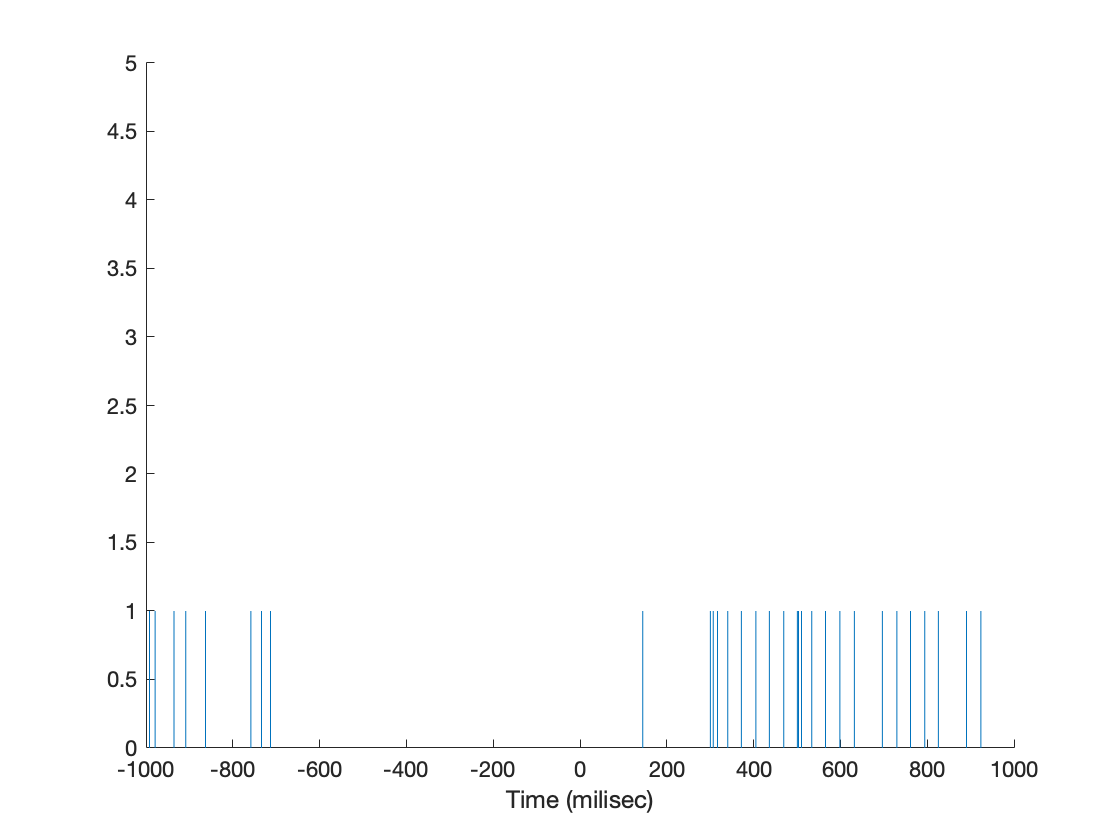

figure %새로운 plot을 시작 
hold on % hold off할 때까지, 모든 plot을 겹쳐서 그림. 각 tick을 한 figure에 담기 위한 세팅.

%Data 1.csv의 raster plot
for i = 1:length(data1msPS) %data2msPS의 첫 원소부터 마지막 원소까지
    line([data1msPS(i) data1msPS(i)], [0 1])  % (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다.
end
hold off
ylim([0 5])
xlabel("Time (milisec)")

## (2) raster plot 두 개 

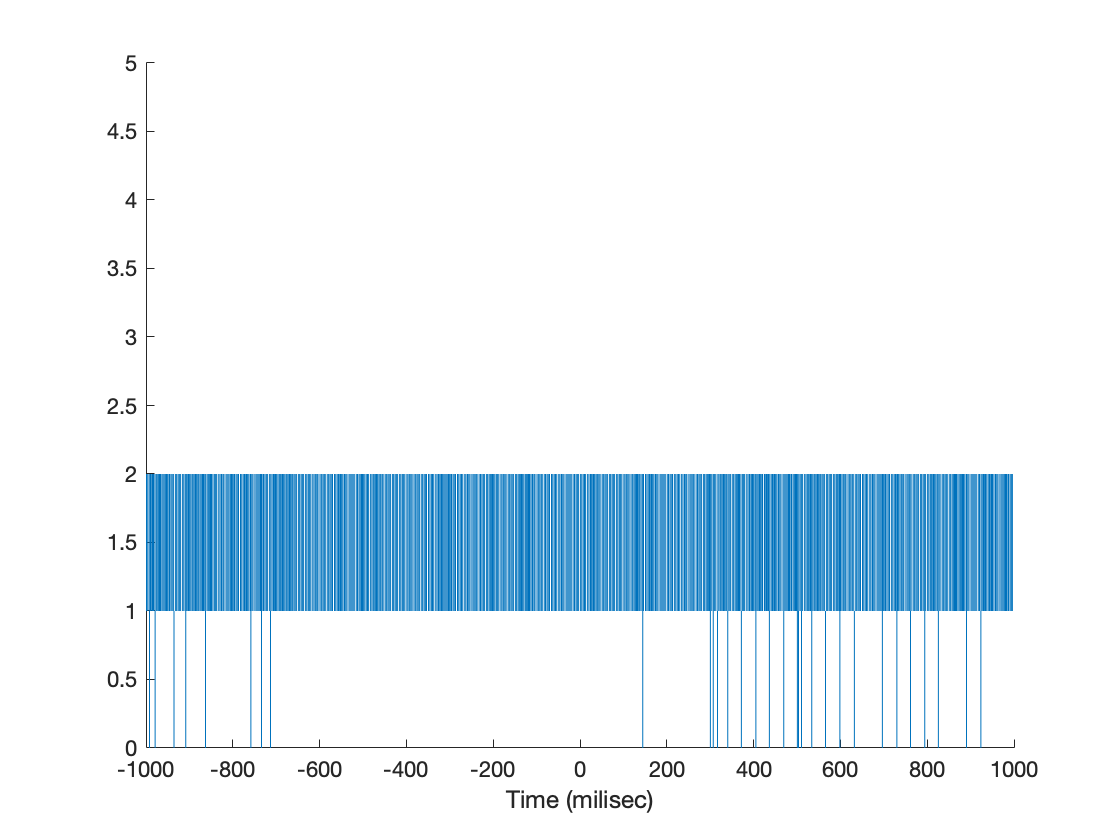

figure %새로운 plot을 시작 
hold on % hold off할 때까지, 모든 plot을 겹쳐서 그림

%Data 1.csv의 raster plot
for i = 1:length(data1msPS) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
    line([data1msPS(i) data1msPS(i)], [0 1])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
end

%Data 2.csv의 raster plot

for j = 1:length(data2msPS)
    line([data2msPS(j) data2msPS(j)], [1 2]) 
end 

hold off
xlim([-1000, 1000]) 
ylim([0 5]) %Reformat y-axis for legibility
xlabel("Time (milisec)") %Label x-axis 

## (3)raster + PSTH

hold on을 잘 활용하면 raster plot과 PSTH를 같이 그릴 수 있습니다. firing rate는 1 이하의 값이므로 raster plot 이 너무 크게 나오지 않게 조절해 주기만 하면 됩니다.

또는 그냥 두 개 figure를 x축만 통일한 후 위아래로 잘 붙여도 됩니다.

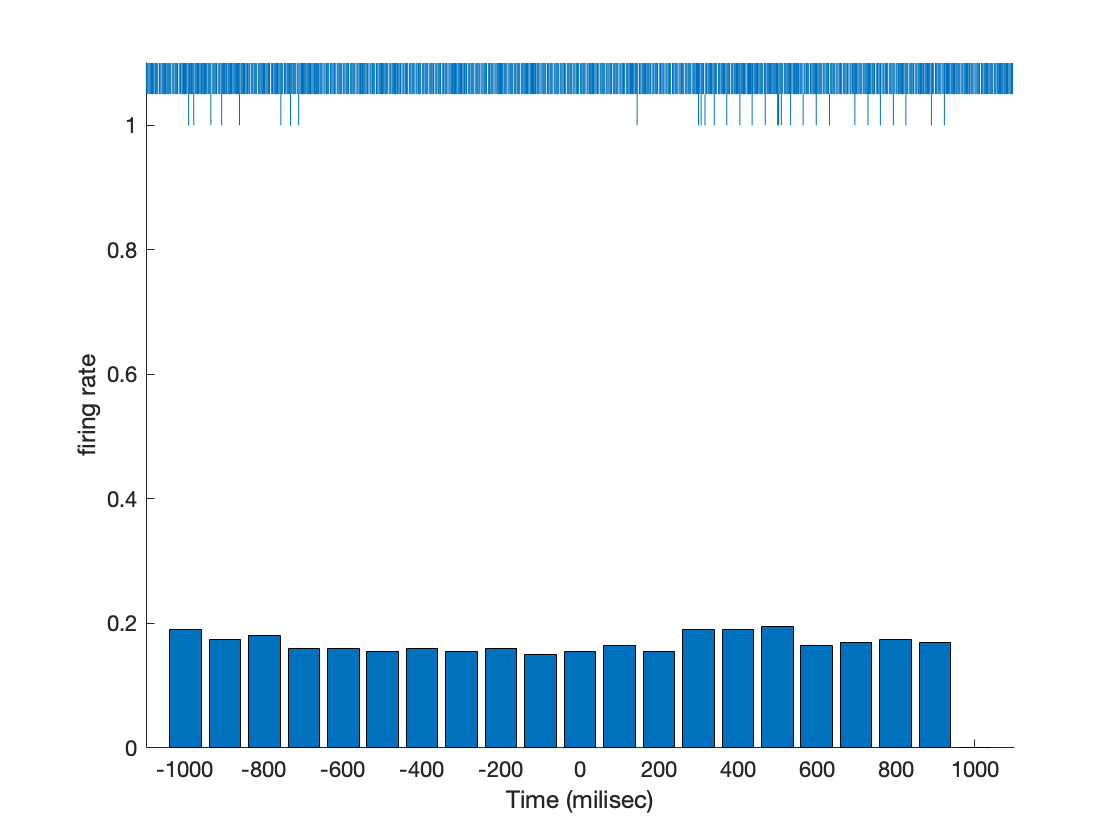

%PSTH

% 1. edges

edges = [-1000: 100: 1000]; %시작점 : 구간길이 : 끝점
psth = zeros(length(edges),1)'; %Initialize the PSTH with zeros

%2. histc with for loop
for j  = 1:2
    psth = psth + histc(dataBundle(j).times,edges);
end
psth = (psth / 100) / 2; %averaging

%3. bar
figure
hold on

bar(edges,psth); %Plot PSTH as a bar graph 


%raster
%Data 1.csv의 raster plot
for i = 1:length(data1msPS) %data2msPS의 첫 원소부터 마지막 원소까지 (Loop through each spike time )
    line([data1msPS(i) data1msPS(i)], [1, 1.05])  % 두 점 (data1msPS(i), 0)과 (data1msPS(i), 1)을 잇는 선, 즉 길이 1짜리 수직선을 그린다(Create a tick mark at x = t1(i) with a height of 1).
end

%Data 2.csv의 raster plot

for j = 1:length(data2msPS)
    line([data2msPS(j) data2msPS(j)], [1.05, 1.1]) 
end 

hold off

ylim([0 1.1]) %Reformat y-axis for legibility

xlim([-1100, 1100]);%Set limits of X-axis 
xlabel('Time (milisec)');%Label x-axis
ylabel('firing rate'); %Label y-axis 